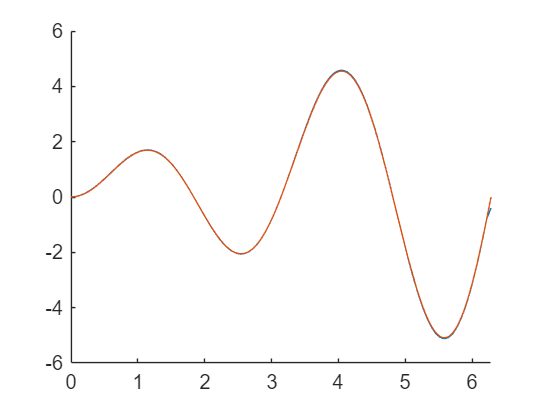

clear all;
close all;
clc;

syms f x;

f = 1 + x*(sin(x)*sin(x));

n = 100;
x_list = linspace(0,2*pi,n);
func = @(x) 1 + x.*sin(x).*sin(x);
f_list = func(x_list);

%fplot(x,f,[0,2*pi])
hold on
%plot(x_list,f_list)

f_m_rec = mean(f_list);
f_d = diff(f);
f_rec_d = gradient(f_list,2*pi/n);
plot(x_list,f_rec_d);
fplot(x,f_d,[0,2*pi]);

x0 = 0;
x1 = 2*pi;
disp([mean(f_list),std(f_list),skewness(f_list),kurtosis(f_list)]);

    2.5551    1.5026    0.9016    2.5577



mean_f = eval(int(f,[x0,x1])/(x1-x0));
std_f = eval(sqrt(int((f - mean_f)^2,[x0,x1])/(x1-x0)));
skew_f = eval(int((f - mean_f)^3,[x0,x1])/(x1-x0)/std_f^3);
kurt_f = eval(int((f - mean_f)^4,[x0,x1])/(x1-x0)/std_f^4);
disp([mean_f,std_f,skew_f,kurt_f])

    2.5708    1.4943    0.8918    2.5384

